# Actividad 7.1 (Waypoints)

Lo que se realiza en esta activdad es definir lo waypoints en el orden que quieres que el robot recorra dichos waypoints. El programa que nos compartío el profesor  es un controlador de seguimiento de trayectoria llamado Pure Pursuit Controller que “persigue” un punto adelantado sobre la trayectoria, llamado punto objetivo, que se encuentra a una cierta distancia hacia adelante (llamada *Lookahead Distance*). El codigo se enfoca en el control de movimiento sobre una trayectoria predefinida. Este tipo de control sería utilizado *después* de que un sistema SLAM ya haya hecho el mapeo y la localización, y entonces el robot pueda ejecutar una trayectoria planificada dentro del mapa.

Para esta actividad cambiamos los paramatros de muestreo, tiempo de simulación, velocidades angular y linear y la nueva variable lookAhead Distance para hacer una trayectoria satisfcatoria.

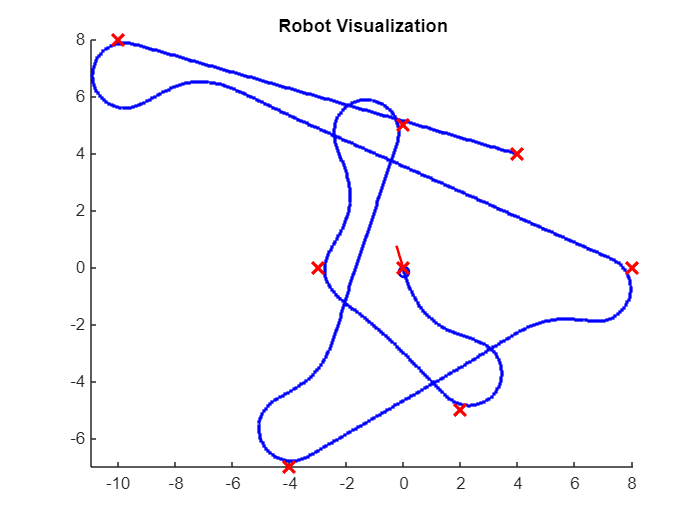

%%Define Vehicle
R=0.1; %Wheel raidus m
L=0.5; %Wheel base
dd=DifferentialDrive(R,L);

%Simulation parameters
sampleTime=0.01;  %Sample time
tVec= 0:sampleTime:81.5; %Time array

initPose=[4;4;160];  %Initial pose (x y theta)
pose=zeros(3,numel(tVec));    %Pose matrix
pose(:,1)=initPose;

%Define waypoints
waypoints=[4,4;-10,8; 8,0; -4,-7; 0,5;-3,0;2,-5;0,0];

%create visualizer
viz=Visualizer2D;
viz.hasWaypoints=true;

%Pure Pursuit Controller
controller=controllerPurePursuit;
controller.Waypoints=waypoints;
controller.LookaheadDistance=1;
controller.DesiredLinearVelocity=1.08;
controller.MaxAngularVelocity=0.95;

%Simulación loop

r=rateControl(1/sampleTime);
for idx =2:numel(tVec)
    [vRef,wRef]=controller(pose(:,idx-1));
    [wL,wR]=inverseKinematics(dd,vRef,wRef);
    
    %Compute the velocities
    [v,w]=forwardKinematics(dd,wL,wR);
    velB=[v;0;w]; %Body velocities
    vel=bodyToWorld(velB,pose(:,idx-1));

    %Perform forward discrete integration step

    pose (:,idx)=pose (:,idx-1)+vel*sampleTime;

end         
% Crear visualizador después de simular
viz = Visualizer2D;
viz.hasWaypoints = true;

% Reproducir la animación con velocidad ajustada
for idx = 1:10:numel(tVec)  % Muestra cada 10 pasos para fluidez (~10 FPS)
    viz(pose(:,idx), waypoints);
    pause(0.001);  % Tiempo entre cuadros (ajustable para más velocidad o suavidad)
end

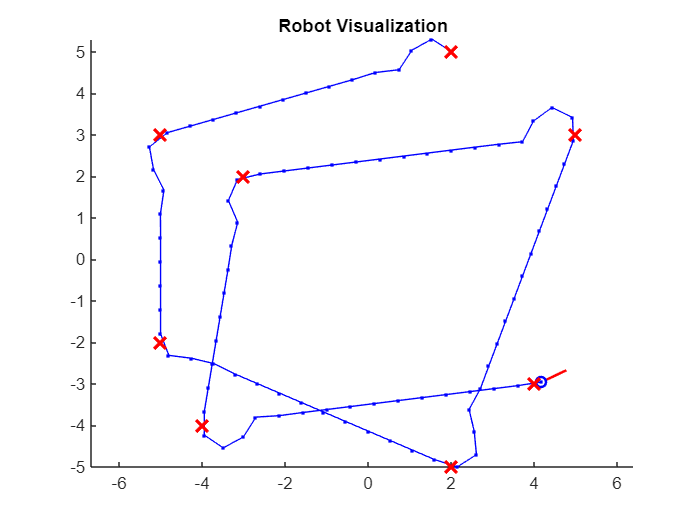



%%Define Vehicle
R=0.1; %Wheel raidus m
L=0.5; %Wheel base
dd=DifferentialDrive(R,L);

%Simulation parameters
sampleTime=0.1;  %Sample time
tVec= 0:sampleTime:93; %Time array

initPose=[2;5;178];  %Initial pose (x y theta)
pose=zeros(3,numel(tVec));    %Pose matrix
pose(:,1)=initPose;

%Define waypoints
waypoints=[2,5;-5,3; -5,-2; 2,-5; 5,3;-3,2;-4,-4;4,-3];

%create visualizer
viz=Visualizer2D;
viz.hasWaypoints=true;

%Pure Pursuit Controller
controller=controllerPurePursuit;
controller.Waypoints=waypoints;
controller.LookaheadDistance=0.15;
controller.DesiredLinearVelocity=0.58;
controller.MaxAngularVelocity=1.09;

%Simulación loop

r=rateControl(1/sampleTime);
for idx =2:numel(tVec)
    [vRef,wRef]=controller(pose(:,idx-1));
    [wL,wR]=inverseKinematics(dd,vRef,wRef);
    
    %Compute the velocities
    [v,w]=forwardKinematics(dd,wL,wR);
    velB=[v;0;w]; %Body velocities
    vel=bodyToWorld(velB,pose(:,idx-1));

    %Perform forward discrete integration step

    pose (:,idx)=pose (:,idx-1)+vel*sampleTime;

end         
% Crear visualizador después de simular
viz = Visualizer2D;
viz.hasWaypoints = true;

% Reproducir la animación con velocidad ajustada
for idx = 1:10:numel(tVec)  % Muestra cada 10 pasos para fluidez (~10 FPS)
    viz(pose(:,idx), waypoints);
    pause(0.001);  % Tiempo entre cuadros (ajustable para más velocidad o suavidad)
end

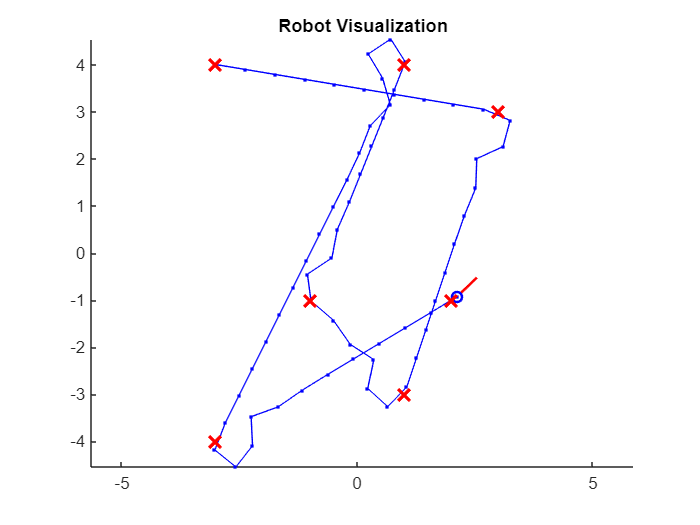


%%Define Vehicle
R=0.1; %Wheel raidus m
L=0.5; %Wheel base
dd=DifferentialDrive(R,L);

%Simulation parameters
sampleTime=0.08;  %Sample time
tVec= 0:sampleTime:51; %Time array

initPose=[-3;4;0];  %Initial pose (x y theta)
pose=zeros(3,numel(tVec));    %Pose matrix
pose(:,1)=initPose;

%Define waypoints
waypoints=[-3,4;3,3; 1,-3; -1,-1; 1,4;-3,-4;2,-1];

%create visualizer
viz=Visualizer2D;
viz.hasWaypoints=true;

%Pure Pursuit Controller
controller=controllerPurePursuit;
controller.Waypoints=waypoints;
controller.LookaheadDistance=0.09;
controller.DesiredLinearVelocity=0.8;
controller.MaxAngularVelocity=1.99;

%Simulación loop
close all
r=rateControl(1/sampleTime);
for idx =2:numel(tVec)
    [vRef,wRef]=controller(pose(:,idx-1));
    [wL,wR]=inverseKinematics(dd,vRef,wRef);
    
    %Compute the velocities
    [v,w]=forwardKinematics(dd,wL,wR);
    velB=[v;0;w]; %Body velocities
    vel=bodyToWorld(velB,pose(:,idx-1));

    %Perform forward discrete integration step

    pose (:,idx)=pose (:,idx-1)+vel*sampleTime;

end         
% Crear visualizador después de simular
viz = Visualizer2D;
viz.hasWaypoints = true;

% Reproducir la animación con velocidad ajustada
for idx = 1:10:numel(tVec)  % Muestra cada 10 pasos para fluidez (~10 FPS)
    viz(pose(:,idx), waypoints);
    pause(0.001);  % Tiempo entre cuadros (ajustable para más velocidad o suavidad)
end

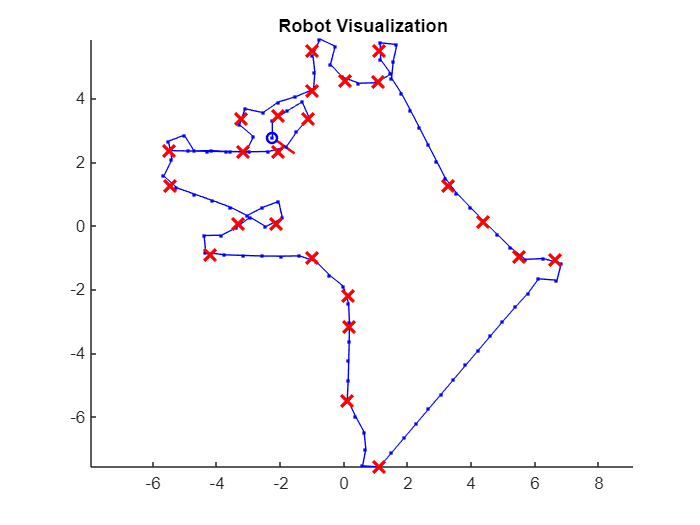


%%Define Vehicle
R=0.1; %Wheel raidus m
L=0.5; %Wheel base
dd=DifferentialDrive(R,L);

%Simulation parameters
sampleTime=0.08;  %Sample time
tVec= 0:sampleTime:82; %Time array

initPose=[-5.49;2.36;0];  %Initial pose (x y theta)
pose=zeros(3,numel(tVec));    %Pose matrix
pose(:,1)=initPose;

%Define waypoints
waypoints = [
   -5.49,  2.36;  % C
   -3.17,  2.32;  % D
   -3.23,  3.36;  % E
   -1.01,  4.26;  % F
   -0.99,  5.52;  % G
    0.05,  4.56;  % H
    1.07,  4.52;  % I
    1.11,  5.52;  % J
    3.29,  1.28;  % K
    4.39,  0.14;  % L
    5.51, -0.96;  % M
    6.63, -1.06;  % N
    1.11, -7.58;  % O
    0.11, -5.50;  % P
    0.17, -3.18;  % Q
    0.13, -2.18;  % R
   -1.00, -1.00;  % S
   -4.19, -0.90;  % T
   -3.33,  0.06;  % U
   -2.13,  0.08;  % V
   -5.45,  1.26 
   -5.49,  2.36;
   -3.17,  2.32;
   -2.07,  2.34;
   -1.13,  3.36;
   -2.07,  3.46;
   -2.07,  2.34;
];


%create visualizer
viz=Visualizer2D;
viz.hasWaypoints=true;

%Pure Pursuit Controller
controller=controllerPurePursuit;
controller.Waypoints=waypoints;
controller.LookaheadDistance=0.09;
controller.DesiredLinearVelocity=0.75;
controller.MaxAngularVelocity=2.13;

%Simulación loop

r=rateControl(1/sampleTime);
for idx =2:numel(tVec)
    [vRef,wRef]=controller(pose(:,idx-1));
    [wL,wR]=inverseKinematics(dd,vRef,wRef);
    
    %Compute the velocities
    [v,w]=forwardKinematics(dd,wL,wR);
    velB=[v;0;w]; %Body velocities
    vel=bodyToWorld(velB,pose(:,idx-1));

    %Perform forward discrete integration step

    pose (:,idx)=pose (:,idx-1)+vel*sampleTime;

end         
% Crear visualizador después de simular
viz = Visualizer2D;
viz.hasWaypoints = true;

% Reproducir la animación con velocidad ajustada
for idx = 1:10:numel(tVec)  % Muestra cada 10 pasos para fluidez (~10 FPS)
    viz(pose(:,idx), waypoints);
    pause(0.001);  % Tiempo entre cuadros (ajustable para más velocidad o suavidad)
end

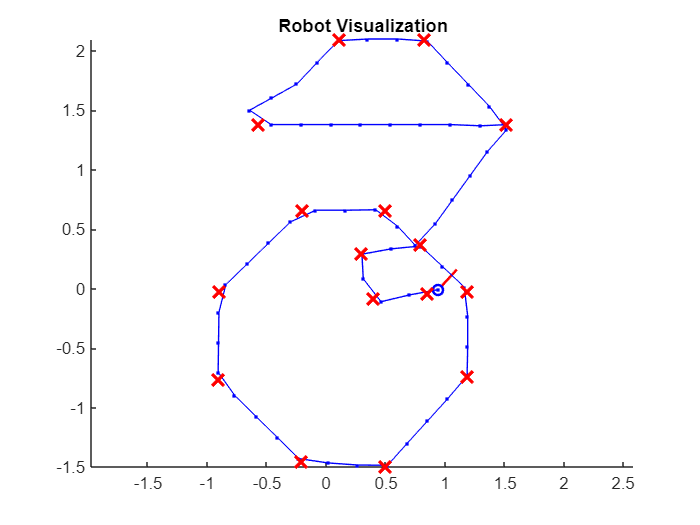


%%Define Vehicle
R=0.1; %Wheel raidus m
L=0.5; %Wheel base
dd=DifferentialDrive(R,L);

%Simulation parameters
sampleTime=0.04;  %Sample time
tVec= 0:sampleTime:23.2; %Time array

initPose=[ 1.52;1.38;180];  %Initial pose (x y theta)
pose=zeros(3,numel(tVec));    %Pose matrix
pose(:,1)=initPose;

%Define waypoints
% Define waypoints
waypoints = [  1.52,  1.38;   % A
              -0.57,  1.38;   % C
               0.11,  2.10;   % D
               0.83,  2.10;   % E
               1.52,  1.38;   % F (≈A)
               0.79,  0.37;   % G
               0.50,  0.66;   % H
              -0.20,  0.66;   % I
              -0.90, -0.02;   % J
              -0.91, -0.76;   % K
              -0.21, -1.45;   % L
               0.50, -1.50;   % M
               1.19, -0.74;   % N
               1.19, -0.02;   % O
               0.79,  0.37;
               0.3,  0.3;% P (≈G)
               0.4, -0.08;   % Q
               0.85, -0.04 ]; % R


%create visualizer
viz=Visualizer2D;
viz.hasWaypoints=true;

%Pure Pursuit Controller
controller=controllerPurePursuit;
controller.Waypoints=waypoints;
controller.LookaheadDistance=0.08;
controller.DesiredLinearVelocity=0.63;
controller.MaxAngularVelocity=5.35;

%Simulación loop

r=rateControl(1/sampleTime);
for idx =2:numel(tVec)
    [vRef,wRef]=controller(pose(:,idx-1));
    [wL,wR]=inverseKinematics(dd,vRef,wRef);
    
    %Compute the velocities
    [v,w]=forwardKinematics(dd,wL,wR);
    velB=[v;0;w]; %Body velocities
    vel=bodyToWorld(velB,pose(:,idx-1));

    %Perform forward discrete integration step

    pose (:,idx)=pose (:,idx-1)+vel*sampleTime;

end         
% Crear visualizador después de simular
viz = Visualizer2D;
viz.hasWaypoints = true;

% Reproducir la animación con velocidad ajustada
for idx = 1:10:numel(tVec)  % Muestra cada 10 pasos para fluidez (~10 FPS)
    viz(pose(:,idx), waypoints);
    pause(0.001);  % Tiempo entre cuadros (ajustable para más velocidad o suavidad)
end

Para esta figura un tiempo de muestreo bajo fue clave para poder dar esa vueltas cerradas que la trayectoria necesitaba

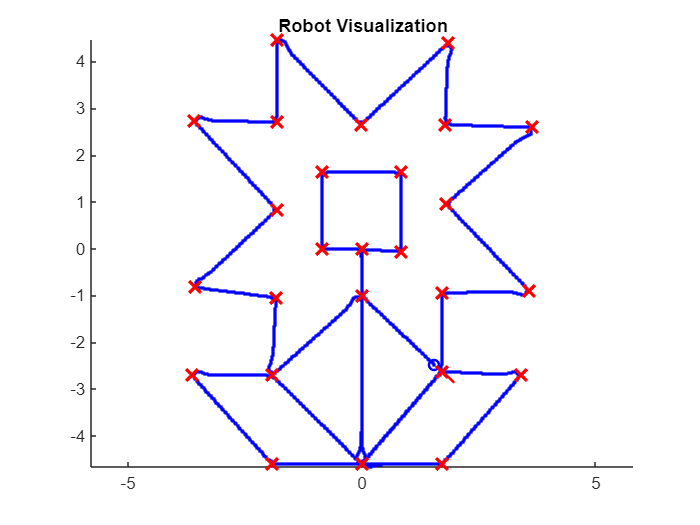

%%Define Vehicle
R=0.1; %Wheel raidus m
L=0.5; %Wheel base
dd=DifferentialDrive(R,L);

%Simulation parameters
sampleTime=0.01; %Sample time
tVec= 0:sampleTime:156.7; %Time array

initPose=[ 1.73;-4.6;pi];  %Initial pose (x y theta)
pose=zeros(3,numel(tVec));    %Pose matrix
pose(:,1)=initPose;

%Define waypoints

waypoints = [  
    1.73, -4.6;
   -1.91, -4.6;
   -3.63, -2.7;
   -1.91, -2.7;
   -0.0, -4.6;
    0.00, -1.0;
   -1.91, -2.7;
   -1.83, -1.04;
   -3.57, -0.82;
   -1.81,  0.84;
   -3.59,  2.74;
   -1.81,  2.72;
   -1.81,  4.48;
   -0.01,  2.66;
    1.85,  4.4;
    1.79,  2.66;
    3.65,  2.6;
    1.81,  0.96;
    3.59, -0.9;
    1.71, -0.94;
    1.71, -2.62;
   -0.0, -4.6;
    1.73, -4.6;
    3.41, -2.7;
    1.71, -2.62;
   -0.0, -4.6;
    0.00, -1.0;
    0.00,  0.0;
    0.85, -0.06;
    0.85,  1.64;
   -0.85,  1.64;
   -0.85,  0.0;
    0.00,  0.0;
    0.00, -1.0;
    1.71, -2.62;
    
];


%create visualizer
viz=Visualizer2D;
viz.hasWaypoints=true;

%Pure Pursuit Controller
controller=controllerPurePursuit;
controller.Waypoints=waypoints;
controller.LookaheadDistance=0.15;
controller.DesiredLinearVelocity=0.45;
controller.MaxAngularVelocity=4.75;

%Simulación loop

r=rateControl(1/sampleTime);
for idx =2:numel(tVec)
    [vRef,wRef]=controller(pose(:,idx-1));
    [wL,wR]=inverseKinematics(dd,vRef,wRef);
    
    %Compute the velocities
    [v,w]=forwardKinematics(dd,wL,wR);
    velB=[v;0;w]; %Body velocities
    vel=bodyToWorld(velB,pose(:,idx-1));

    %Perform forward discrete integration step

    pose (:,idx)=pose (:,idx-1)+vel*sampleTime;

end         
% Crear visualizador después de simular
viz = Visualizer2D;
viz.hasWaypoints = true;

% Reproducir la animación con velocidad ajustada
for idx = 1:10:numel(tVec)  % Muestra cada 10 pasos para fluidez (~10 FPS)
    viz(pose(:,idx), waypoints);
    pause(0.001);  % Tiempo entre cuadros (ajustable para más velocidad o suavidad)
end